# Larger networks

stim_options = get_default_stim_options();
stim_options.num_comms = 3;
stim_options.num_nodes_per_comm = 20;
stim_options.in_dsity = .65;
stim_options.out_dsity = .01;
stim_options.hub_dsity = .10;
stim_options = make_connectivity_matrix(stim_options);

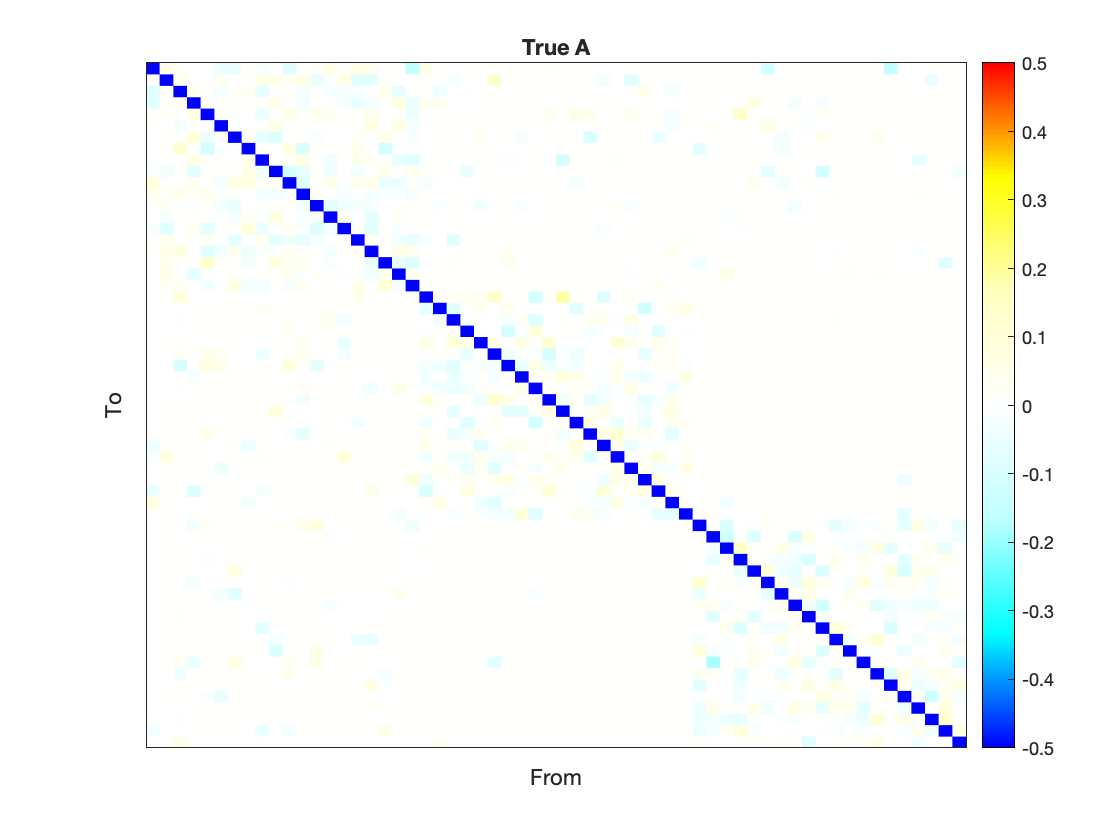

plot_connectivity(stim_options.Tp.A)

Bursty task failed on dense network with primarily excitatory connections.

Impulse failed on dense network with primarily excitatory connections.

Impulse worked on dense network with excitatory and inhibitory connections coming from one distribution centered at 0.

tasktiming = [zeros(1, 88), 1, zeros(1, 4000)];
stim_options.u_dt = stim_options.TR/16;

stim_options.stim_node = 1:5;
stim_options.u = zeros(length(tasktiming), stim_options.n);
for i=1:length(stim_options.stim_node)
    stim_options.u(:, stim_options.stim_node(i)) = tasktiming;
end

% clf
% plot(stim_options.u)

[DCM, options] = make_task_fmri(stim_options);

if sum(sum(isnan(DCM.Y.y))) > 0
    fprintf("Failed!");
else
    fprintf("Worked!");
end

Worked!

Plot activity by community

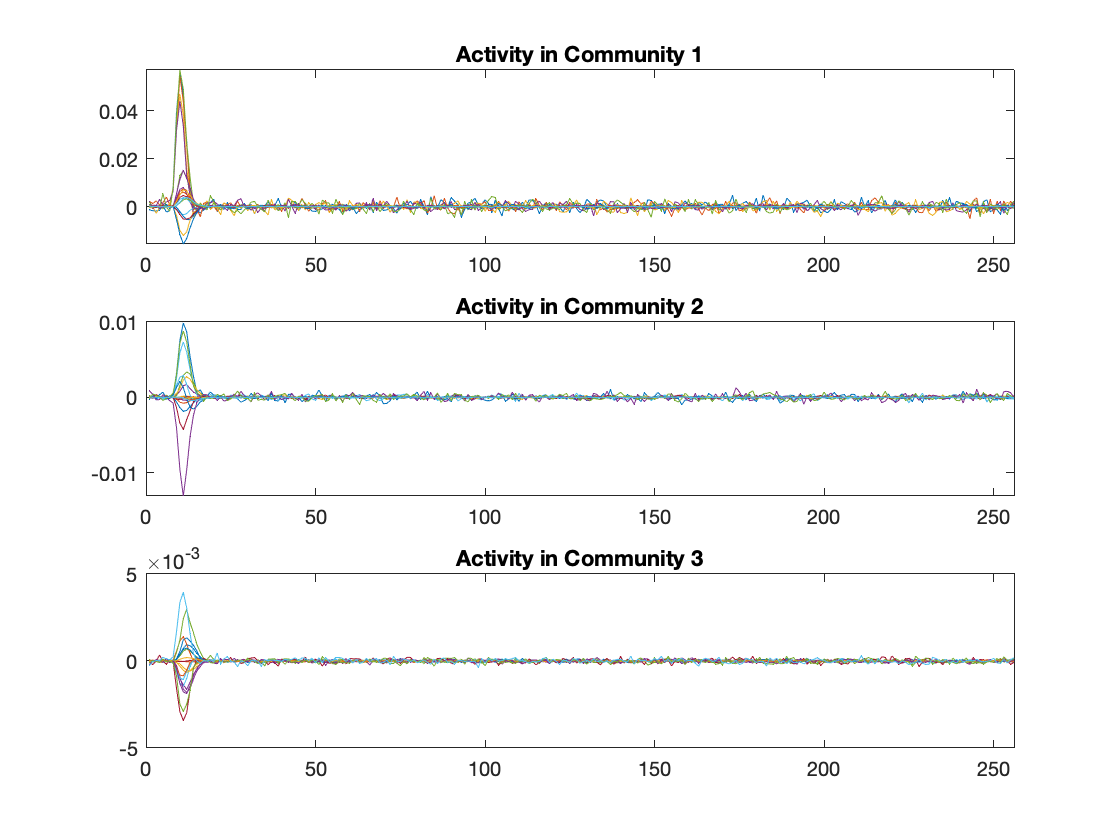

for i=1:stim_options.num_comms
    subplot(stim_options.num_comms, 1, i)
    plot(DCM.Y.y(:,(i-1)*stim_options.num_nodes_per_comm+1:i*stim_options.num_nodes_per_comm))
    title(sprintf("Activity in Community %.0f", i));
    xlim([0, length(DCM.Y.y)])
end

Would a short burst task also work?

on_len = 2;
off_len = 15;
num_blocks = stim_options.T/(on_len + 2*off_len);
tasktiming = repmat([zeros(1, off_len), ones(1, on_len), zeros(1, off_len)], 1, num_blocks);
stim_options.u_dt = stim_options.TR/16;
tasktiming = interp1(1:stim_options.T, tasktiming, 1:stim_options.u_dt:stim_options.T, "linear");
tasktiming = double(logical(tasktiming));

stim_options.stim_node = 1:5;
stim_options.u = zeros(length(tasktiming), stim_options.n);
for i=1:length(stim_options.stim_node)
    stim_options.u(:, stim_options.stim_node(i)) = tasktiming;
end

[DCM, options] = make_task_fmri(stim_options);

if sum(sum(isnan(DCM.Y.y))) > 0
    fprintf("Failed!");
else
    fprintf("Worked!");
end

Worked!

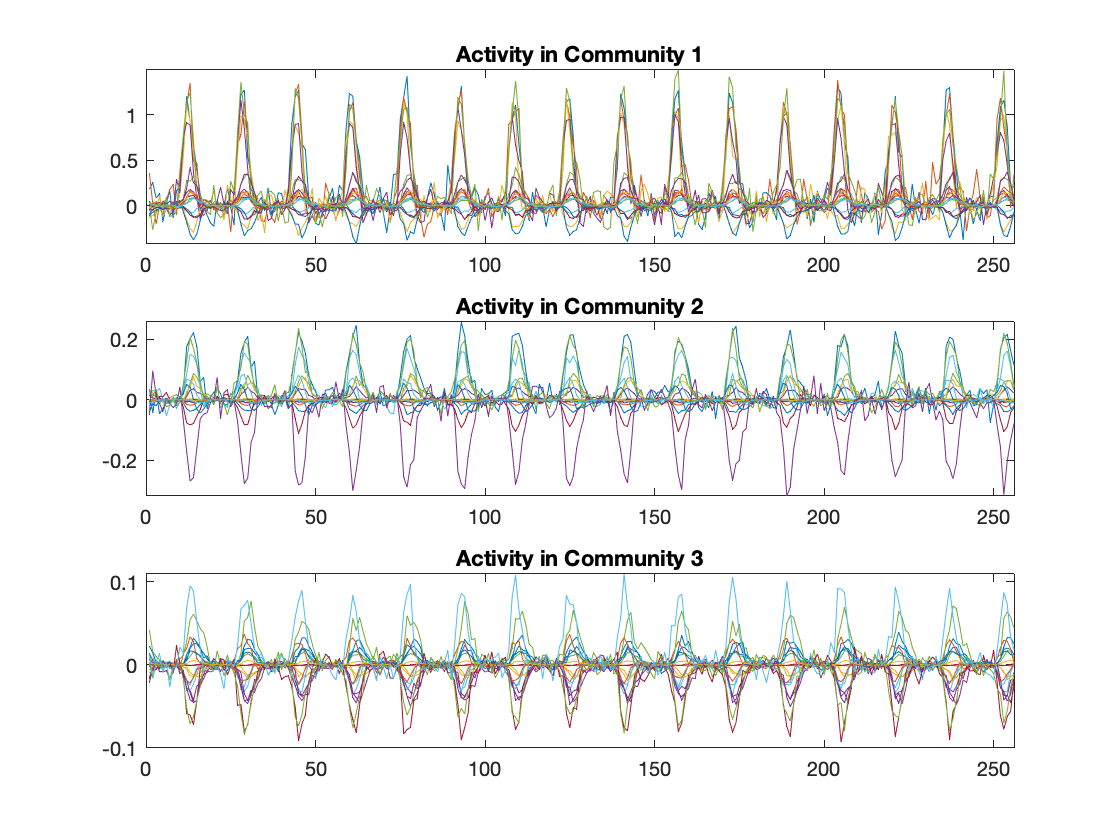

for i=1:stim_options.num_comms
    subplot(stim_options.num_comms, 1, i)
    plot(DCM.Y.y(:,(i-1)*stim_options.num_nodes_per_comm+1:i*stim_options.num_nodes_per_comm))
    title(sprintf("Activity in Community %.0f", i));
    xlim([0, length(DCM.Y.y)])
end

How about a task with long on but even longer off periods?

on_len = 28;
off_len = 50;
num_blocks = stim_options.T/(on_len + 2*off_len);
tasktiming = repmat([zeros(1, off_len), ones(1, on_len), zeros(1, off_len)], 1, num_blocks);
stim_options.u_dt = stim_options.TR/16;
tasktiming = interp1(1:stim_options.T, tasktiming, 1:stim_options.u_dt:stim_options.T, "linear");
tasktiming = double(logical(tasktiming));

stim_options.stim_node = 1:5;
stim_options.u = zeros(length(tasktiming), stim_options.n);
for i=1:length(stim_options.stim_node)
    stim_options.u(:, stim_options.stim_node(i)) = tasktiming;
end

[DCM, options] = make_task_fmri(stim_options);

if sum(sum(isnan(DCM.Y.y))) > 0
    fprintf("Failed!");
else
    fprintf("Worked!");
end

Worked!

for i=1:stim_options.num_comms
    subplot(stim_options.num_comms, 1, i)
    plot(DCM.Y.y(:,(i-1)*stim_options.num_nodes_per_comm+1:i*stim_options.num_nodes_per_comm))
    title(sprintf("Activity in Community %.0f", i));
    xlim([0, length(DCM.Y.y)])
end